# Computational burden calculation

Imperix: 2600 flops = 15% CPU burden

cpu_flops_ratio = 15/2600;
cpu_flops_ratio = 10/2600;

## Neural Network

nx = 14;     % Inputs
nl = 3;      % Hidden layers
nh = 5 * nx; % Neurons per hidden layer
ny = 3;      % Outputs
NN_mults = nh * (nx + 1) + (nl - 1) * nh * (nh + 1) + ny * (nh + 1) %+ nl * nh

NN_mults = 11203

NN_sums  = nh * nx + (nl - 1) * nh * nh + ny * nh %+ nl * nh

NN_sums = 10990

NN_relu_operations = nh * nl

NN_relu_operations = 210

NN_tanh_operations = ny

NN_tanh_operations = 3

NN_flops = NN_mults + NN_sums + NN_relu_operations + NN_tanh_operations

NN_flops = 22406

NN_CPU_burden = NN_flops * cpu_flops_ratio

NN_CPU_burden = 86.1769

## LONG HORIZON Block Coordinate Descent

Nl = 50; % BCD Iterations
Np = 10; % Horizon length
n = 2;   % Circulating currents

BCD_cholesky = Nl * (Np^3 + (n * Np)^3) / 6

BCD_cholesky = 75000

BCD_triang_solutions = Nl * (Np^2 + (n * Np)^2) / 2

BCD_triang_solutions = 12500

BCD_H_inv_flops = BCD_cholesky + 2 * BCD_triang_solutions

BCD_H_inv_flops = 100000


BCD_mv_multiplication_mults = Nl * Np * (Np + n * n * Np)

BCD_mv_multiplication_mults = 25000

BCD_mv_multiplication_sums = Nl * Np * ((Np - 1) + n * (n * Np - 1))

BCD_mv_multiplication_sums = 23500

BCD_mv_flops = BCD_mv_multiplication_mults + BCD_mv_multiplication_sums

BCD_mv_flops = 48500


BCD_flops = BCD_H_inv_flops + BCD_mv_flops

BCD_flops = 148500

BCD_CPU_burden = BCD_flops * cpu_flops_ratio

BCD_CPU_burden = 571.1538

## Computational gain

BCD_flops / NN_flops

ans = 6.6277

clc; clear; close all;

%% 1. Neural Network FLOPs Calculation (Fixed Cost)
nx = 14; nl = 3; nh = 5 * nx; ny = 3;

NN_mults = nh * (nx + 1) + (nl - 1) * nh * (nh + 1) + ny * (nh + 1);
NN_sums  = nh * nx + (nl - 1) * nh * nh + ny * nh;
NN_relu_operations = nh * nl;
NN_tanh_operations = ny;

NN_flops = NN_mults + NN_sums + NN_relu_operations + NN_tanh_operations;
fprintf('Neural Network FLOPs (Fixed): %.0f\n', NN_flops);

Neural Network FLOPs (Fixed): 22406


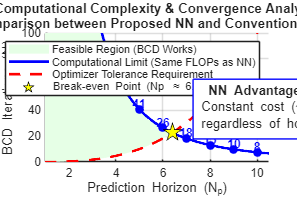


%% 2. BCD Computational Cost Curve (Blue Hyperbola)
% Find Nl such that: BCD_flops(Np, Nl) = NN_flops

n = 2; % Circulating currents
Np_range = 1:0.01:10.5; % Extended slightly past 10 for visualization

% Vectorized cost of 1 BCD iteration
BCD_chol_1it   = (Np_range.^3 + (n * Np_range).^3) / 6;
BCD_triang_1it = (Np_range.^2 + (n * Np_range).^2) / 2;
BCD_H_inv_1it  = BCD_chol_1it + 2 * BCD_triang_1it;
BCD_mv_mult_1it = Np_range .* (Np_range + n * n * Np_range);
BCD_mv_sum_1it  = Np_range .* ((Np_range - 1) + n * (n * Np_range - 1));
BCD_mv_1it      = BCD_mv_mult_1it + BCD_mv_sum_1it;

BCD_cost_per_iter = BCD_H_inv_1it + BCD_mv_1it;

% Max iterations allowed given the NN budget
Nl_budget_curve = NN_flops ./ BCD_cost_per_iter;

%% 3. Tolerance Requirement Curve (Red Dashed Line)
% Power Law fit based on observations: (10, 100) and (20, 1000)
Np_obs = [10, 20];
Nl_obs = [100, 1000];

% Log-Log fit: log(Nl) = log(a) + b * log(Np)
coeffs = polyfit(log(Np_obs), log(Nl_obs), 1);
b_exp = coeffs(1);       
a_coeff = exp(coeffs(2)); 

% Required iterations curve
Nl_required_curve = a_coeff * Np_range .^ b_exp;

%% 4. Plotting
figure('Color', 'w', 'Position', [100 100 900 600]);
hold on; grid on;

% --- A. Feasible Region (Fill) ---
% Find intersection
idx_cross = find(Nl_required_curve > Nl_budget_curve, 1);
if isempty(idx_cross)
    idx_cross = length(Np_range);
end
Np_cross = Np_range(idx_cross);

% Fill area where Budget >= Requirement
x_fill = Np_range(1:idx_cross);
y_top = Nl_budget_curve(1:idx_cross);
y_bot = Nl_required_curve(1:idx_cross);
fill([x_fill, fliplr(x_fill)], [y_top, fliplr(y_bot)], ...
     [0.9, 1, 0.9], 'EdgeColor', 'none', 'DisplayName', 'Feasible Region (BCD Works)');

% --- B. Main Curves ---
% 1. Computational Limit (Blue)
plot(Np_range, Nl_budget_curve, 'b-', 'LineWidth', 2, 'DisplayName', 'Computational Limit (Same FLOPs as NN)');

% 2. Tolerance Requirement (Red)
plot(Np_range, Nl_required_curve, 'r--', 'LineWidth', 2, 'DisplayName', 'Optimizer Tolerance Requirement');

% --- C. Markers on the Hyperbola ---
% Loop through integer horizons from 1 to 10
for k = 1:10
    % Interpolate exact Y value
    val_y = interp1(Np_range, Nl_budget_curve, k);
    
    % Plot round dot
    plot(k, val_y, 'bo', 'MarkerFaceColor', 'b', 'MarkerSize', 6, 'HandleVisibility', 'off');
    
    % Add text label slightly above the dot
    % Adjust vertical offset based on the slope to avoid overlap
    offset = 4;
    if k < 3, offset = 6; end 
    
    text(k, val_y + offset, sprintf('%.0f', val_y), ...
        'Color', 'b', 'FontWeight', 'bold', 'HorizontalAlignment', 'center', 'FontSize', 9);
end

% --- D. Intersection Point ---
plot(Np_cross, Nl_budget_curve(idx_cross), 'p', 'MarkerSize', 14, ...
    'MarkerFaceColor', 'y', 'MarkerEdgeColor', 'k', ...
    'DisplayName', sprintf('Break-even Point (Np \\approx %.1f)', Np_cross));

% --- E. Formatting ---
xlabel('Prediction Horizon (N_p)');
ylabel('BCD Iterations (N_l)');
title({'Computational Complexity & Convergence Analysis', ...
       'Comparison between Proposed NN and Conventional BCD'});
legend('Location', 'northeast');

% Axes limits
xlim([1 10.5]); 
ylim([0 100]); % Adjusted to show the curve clearly

% Text Box for Context
dim = [0.65 0.5 0.2 0.1];
str = {'\bf NN Advantage:', 'Constant cost (~22k FLOPs)', 'regardless of horizon length'};
annotation('textbox', dim, 'String', str, 'FitBoxToText', 'on', 'BackgroundColor', 'w', 'EdgeColor', 'b');